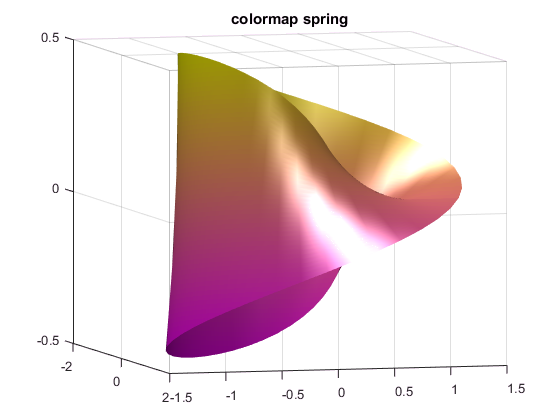

u = linspace(0, 2*pi, 40);
v = linspace(-1, 1, 40);
[U, V] = meshgrid(u, v);
x = (1 + 0.5 * V .* cos(U ./ 2)) .* cos(U);
y = (1 + 0.5 * V .* cos(U ./ 2)) .* sin(U);
z = 0.5 * V .* sin(U ./ 2);
surf(x, y, z, 'FaceColor', 'interp', 'EdgeColor', 'none', 'Facelighting', 'gouraud', 'AmbientStrength', 0.9, 'DiffuseStrength', 0.9)
lightangle(-70, 60)
material metal
colormap(spring), title('colormap spring')
shading interp
camlight
view([16, -6])